# [LSTM Networks](https://apmonitor.com/pds/index.php/Main/LongShortTermMemory)

[**LSTM (Long Short Term Memory) networks**](https://towardsdatascience.com/illustrated-guide-to-lstms-and-gru-s-a-step-by-step-explanation-44e9eb85bf21) are a special type of RNN (Recurrent Neural Network) that is structured to remember and predict based on long-term dependencies that are trained with time-series data. An LSTM repeating module has four interacting components.

The LSTM is trained (parameters adjusted) with an input window of prior data and minimized difference between the predicted and next measured value. Sequential methods predict just one next value based on the window of prior data. When there is contextual data (before and after) the desired prediction point, a [**Convolutional Neural Network (CNN)**](https://en.wikipedia.org/wiki/Convolutional_neural_network) may [**improve performance with fewer resources to train and deploy the network**](https://towardsdatascience.com/the-fall-of-rnn-lstm-2d1594c74ce0).

#### **Data Preparation**

Data preparation for LSTM networks involves consolidation, cleansing, separating the input window and output, scaling, and data division for training and validation.

- Consolidation - consolidation is the process of combining disparate data (Excel spreadsheet, PDF report, database, cloud storage) into a single repository.

- Data Cleansing - bad data should be removed and may include outliers, missing entries, failed sensors, or other types of missing or corrupted information.

- Inputs and Outputs - data is separated into inputs (prior time-series window) and outputs (predicted next value). The inputs are fed into a series of functions to produce the output prediction. The squared difference between the predicted output and the measured output is a typical loss (objective) function for fitting.

- Scaling - scaling all data (inputs and outputs) to a range of 0-1 can improve the training process.

- Training and Validation - data is divided into training (e.g. 80%) and validation (e.g. 20%) sets so that the model fit can be evaluated independently of the training. Cross-validation is an approach to divide the training data into multiple sets that are fit separately. The parameter consistency is compared between the multiple models.

#### **Data Generation and Preparation**

% Generate data
n = 500;
t = linspace(0,20*pi,n);
X = sin(t);

Once the data is generated, it is converted to a form that can be used for training and prediction.

% Set window of past points for LSTM model
window = 10;

% Split 80/20 into train/test data
last = floor(n / 5.0);
Xtrain = X(1:end-last);
Xtest = X(end-last-window+1:end);

% Store window number of points as a sequence
xin = zeros(length(Xtrain)-window, window);
next_X = zeros(length(Xtrain)-window, 1);
for i = window:length(Xtrain)
    xin(i-window+1,:) = Xtrain(i-window+1:i);
    next_X(i-window+1) = Xtrain(i);
end

% Reshape data to format for LSTM
xin = reshape(xin, size(xin,1), size(xin,2), 1);
next_X = reshape(next_X, [], 1);

#### **LSTM Model Build**

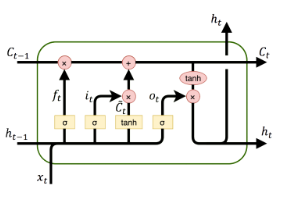

An LSTM network relates the input data window to outputs with layers. Instead of just one layer, LSTMs often have multiple layers.

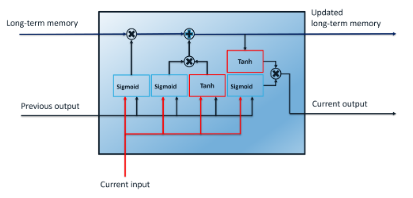

% Set up layers for the LSTM
layers = [ sequenceInputLayer(10)
    lstmLayer(75)
    dropoutLayer(0.2)
    lstmLayer(75)
    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer
    ];

% Clarify more options for the fit
options = trainingOptions('adam', ...
    MaxEpochs=25, ...
    MiniBatchSize=100, ...
    Verbose=true, ...
    Plots='training-progress');

#### **LSTM Model Training**

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:08 |         0.64 |          0.2 |          0.0010 |
|      25 |          25 |       00:00:21 |         0.12 |      7.6e-03 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


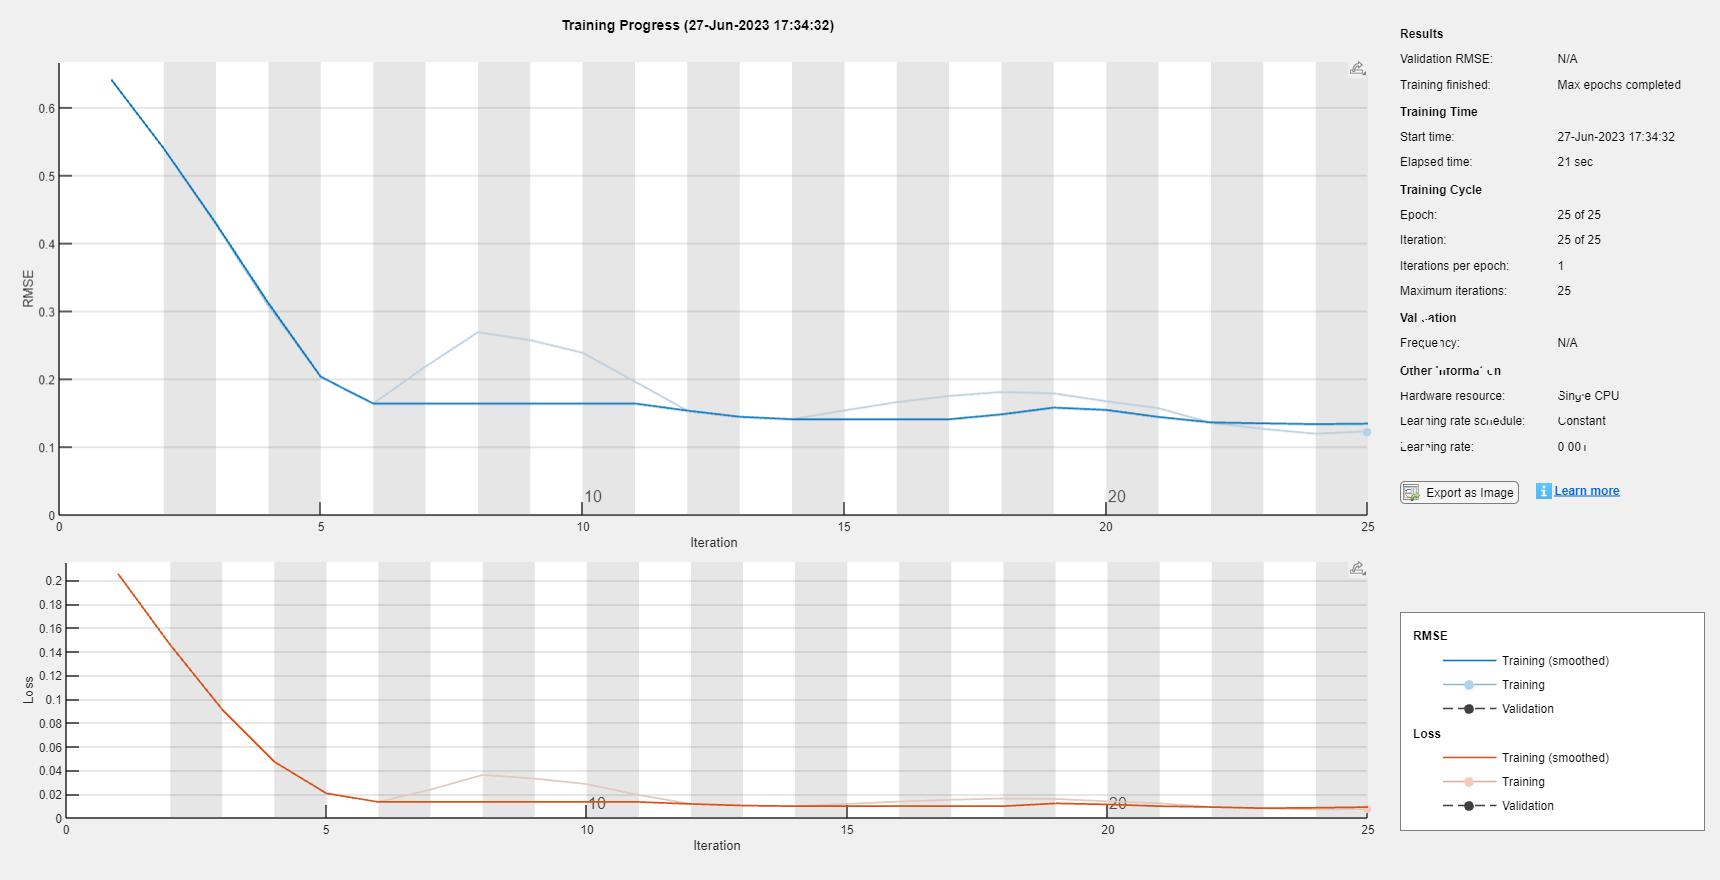

[lstm,~] = trainNetwork(xin',next_X',layers,options);

#### **LSTM Prediction Validation**

The validation test set assesses the ability of the neural network to predict based on new conditions that were not part of the training set. The validation is performed with the last 20% of the data that was separated from the beginning 80% of data.

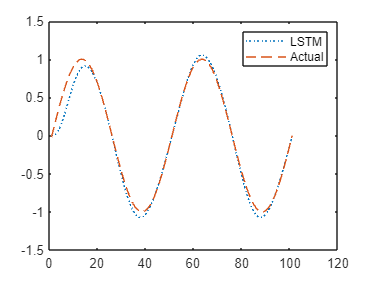

% Store "window" points as a sequence
xin = zeros(length(Xtest)-window, window);
next_X1 = zeros(length(Xtest)-window, 1);
for i = window:length(Xtest)
    xin(i-window+1,:) = Xtest(i-window+1:i);
    next_X1(i-window+1) = Xtest(i);
end

% Reshape data to format for LSTM
xin = reshape(xin, size(xin,1), size(xin,2), 1);
next_X1 = reshape(next_X1, [], 1);

% Predict the next value (1 step ahead)
X_pred = predict(lstm, xin');

% Plot prediction vs actual for test data
figure;
plot(X_pred,':','DisplayName','LSTM');
hold on;
plot(next_X1,'--','DisplayName','Actual');
legend;

#### **LSTM Forecast Validation**

When performing the validation it is also important to determine how the model performs without measurements when it uses prior predictions to predict the next outcome. This is important to determine how well the model performs in a predictive application such as model predictive control where the model is projected forward over the control horizon to determine the sequence of optimal manipulated variable moves and possible future constraint violation. Generating predictions without measurement feedback is a forecast.

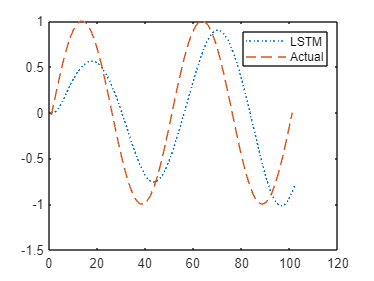

% Using predicted values to predict next step
X_pred1 = Xtest;

for i = window:length(X_pred)+10
    xin1 = reshape(X_pred1(i-window+1:i), 1, window, 1);
    [lstm,X_pred1(i+1)] = predictAndUpdateState(lstm,xin1');
    
end

lstm = resetState(lstm); % This line of code is required if you rerun this block multiple times

% Plot prediction vs actual for test data
figure;
plot(X_pred1(window+1:end), ':', 'DisplayName', 'LSTM');
hold on;
plot(next_X1, '--', 'DisplayName', 'Actual');
legend;

## Exercise 1: LSTM Digital Twin

Develop a model of the dynamic temperature response of the TCLab and compare the LSTM model prediction to a [**second-order linear differential equation solution**](https://apmonitor.com/pdc/index.php/Main/TCLabSecondOrder). Use the [**4 hours of dynamic data from a TCLab**](https://apmonitor.com/do/uploads/Main/tclab_dyn_data3.txt) (14400 data points = 1 second sample rate for 4 hours) for training and generate new data (840 data points = 1 second sample rate for 14 min) for validation (see [**sample validation data**](https://apmonitor.com/pdc/uploads/Main/tclab_data4.txt)).

Use the measured temperature and heater values to predict the next temperature value with an LSTM model. Validate the model with a new data set in a predictive and forecast mode. The predictive mode predicts one step ahead while the forecast does not use temperature measurements to generate the predictions.

clear;

% Load training data
train = readtable('http://apmonitor.com/do/uploads/Main/tclab_dyn_data3.txt');

% Scale features
X = [train.T1,train.Q1];
mu = mean(X,1);
sigma = std(X,0,1);
Xs = (X-mu)./sigma;

% Scale predicted value
Y = [train.T1];
mu = mean(Y,1);
sigma = std(Y,0,1);
Ys = (Y-mu)./sigma;

% Each time step uses last 'window' to predict the next change
window = 70;
X = zeros(length(Xs)-window,window,2);
Y = zeros(length(Xs)-window,1);

for i = window:size(Xs,1)-window
    X(i-window+1,:,:) = Xs(i-window+1:i, :);
    Y(i-window+1) = Ys(i);
end

% Reshape data to format accepted by LSTM
X = permute(X,[3,2,1]);

% Initialize LSTM model
% Set up layers for the LSTM
layers = [ sequenceInputLayer([70,2],'NormalizationDimension','auto')
    flattenLayer()
    lstmLayer(50)
    dropoutLayer(0.2)
    lstmLayer(50,'OutputMode','sequence')
    dropoutLayer(0.2)
    lstmLayer(20,'OutputMode','sequence')
    fullyConnectedLayer(1)
    regressionLayer
    ];

% Clarify more options for the fit
options = trainingOptions('adam', ...
    MaxEpochs=10, ...
    MiniBatchSize=250, ...
    Verbose=true, ...
    ValidationPatience=10, ...
    InitialLearnRate=0.01,...
    Plots='training-progress');

% Fit LSTM model
[lstm,info] = trainNetwork(pagetranspose(X),Y',layers,options); 

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |         0.91 |          0.4 |          0.0100 |
|      10 |          10 |       00:01:25 |         0.30 |      4.4e-02 |          0.0100 |
|========================================================================================|
Training finished: Max epochs completed.


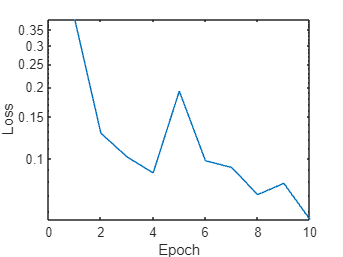

% Plot loss
figure;
semilogy(info.TrainingLoss);
xlabel('Epoch');
ylabel('Loss');
saveas(gcf, 'tclab_loss.png');

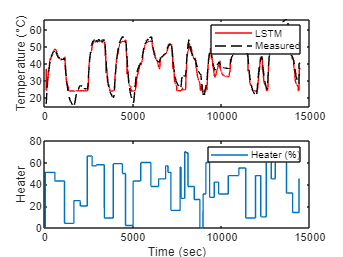


% Verify the fit of the model
Yp = predict(lstm,pagetranspose(X));

% Unscale outputs
Yu = Yp * sigma + mu; 
Ym = Y * sigma + mu;

figure;
subplot(2, 1, 1);
plot(train.Time(window+1:end), Yu, 'r-', 'DisplayName', 'LSTM');
hold on;
plot(train.Time(window+1:end), Ym, 'k--', 'DisplayName', 'Measured');
ylabel('Temperature (°C)');
legend;
subplot(2, 1, 2);
plot(train.Q1, 'DisplayName', 'Heater (%)');
legend;
xlabel('Time (sec)');
ylabel('Heater');
saveas(gcf, 'tclab_fit.png');

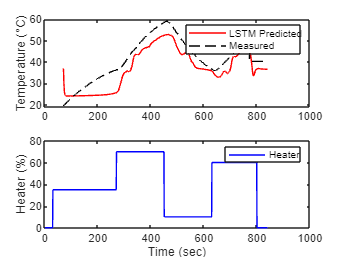


% Load test data
test = readtable('http://apmonitor.com/pdc/uploads/Main/tclab_data4.txt');

Xt = test{:, {'T1', 'Q1'}};
Yt = test.T1;

% Scale features
mu = mean(Xt,1);
sigma = std(Xt,0,1);
Xts = (Xt-mu)./sigma;

% Scale predicted value
mu = mean(Yt,1);
sigma = std(Yt,0,1);
Yts = (Yt-mu)./sigma;

Xti = zeros(length(Xts)-window,window,2);
Yti = zeros(length(Xts)-window,1);
for i = window:size(Xts,1)-window
    Xti(i-window+1,:,:) = Xts(i-window+1:i, :);
    Yti(i-window+1) = Yts(i);
end

% Reshape data to format accepted by LSTM
Xti = permute(Xti,[3,2,1]);

% Verify the fit of the model
Ytp = predict(lstm,pagetranspose(Xti));

% Unscale outputs
Ytu = Ytp * sigma + mu; 
Ytm = Yti * sigma + mu;

figure;
subplot(2, 1, 1);
plot(test.Time(window+1:end), Ytu, 'r-', 'DisplayName', 'LSTM Predicted');
hold on;
plot(test.Time(window+1:end), Ytm, 'k--', 'DisplayName', 'Measured');
legend;
ylabel('Temperature (°C)');
subplot(2, 1, 2);
plot(test.Time, test.Q1, 'b-', 'DisplayName', 'Heater');
legend;
xlabel('Time (sec)');
ylabel('Heater (%)');
saveas(gcf, 'tclab_validate.png');